# 6DOF SIMULATION OF LUNAR LANDER

clear all; close all;
global m Ixx Iyy Izz roll0 dt t_go
global K_phi K_P K_theta K_Q K_psi K_R

h = 1500;

Ixx = 2500;
Iyy = 4500;
Izz = 350;

K_phi = 62500;
K_P = 21250;
K_theta = 112500;
K_Q = 38250;
K_psi = 8750;
K_R = 2975;


## INITIALIZE STATE

%pos = [0 0 -h];   % n-frame
%vel = [0 0 30];
pos = [100 0 -h];   % n-frame
%pos = [-700 0 -h];   % n-frame
ang = [0 0 0];   % rad

C_b2n = [cos(ang(2))*cos(ang(3)) cos(ang(2))*sin(ang(3)) -sin(ang(2));...
    sin(ang(1))*sin(ang(2))-cos(ang(1))*sin(ang(3)) sin(ang(1))*sin(ang(2))*sin(ang(3))+cos(ang(1))*cos(ang(3)) sin(ang(1))*cos(ang(2));...
    cos(ang(1))*sin(ang(2))*cos(ang(3))+sin(ang(1))*sin(ang(3)) cos(ang(1))*sin(ang(2))*sin(ang(3))-sin(ang(1))*cos(ang(3)) cos(ang(1))*cos(ang(2))]';
vel_I = [-25 0 80];
%vel_I = [-10 0 80];
vel = (C_b2n'*vel_I')';


ang_vel = [0 0 0];
roll0 = 0;

m = 2100;  % mass of lunar-lander, kg

initial_state = [pos vel ang ang_vel];  % I-frame
state_t = [0 0 0 0 0 0];    % I-frame


## SIMULATION

dt = 0.01;

i = 1;
t_go = 30;
tic

% [acc,t_go] = guidance_moon(initial_state,state_t);  % n-frame
state = initial_state; 
% acc = guidance_moon_final(state,state_t);


z = state(3);

acc_temp = guidance_moon_final(state,state_t);

state =          100           0       -1500         -25           0          80           0           0           0           0           0           0


lsqr이(가) 반복 2에서 해로 수렴했습니다(상대 잔차: 6.9e-14).


% acc = kron(acc_temp,ones(10,1));
acc = acc_temp;

% acc = kron(acc_,ones(100,1));

%acc = zeros(5000,3);
%acc(:,1) = 0.1*ones(5000,1);
%acc(:,2) = 0.1*ones(5000,1);
%acc(:,3) = -ones(5000,1);

dt = 0.1;
while i <= t_go/dt
    save_state(i,:) = state;  % n-frame
%     state(7:9) = ang_limit(state(7:9));
    
%     if rem(i,10) == 0
%         acc_temp = guidance_moon_final(state,state_t);
%         acc(i:i+9,:) = kron(acc_temp,ones(10,1));
%     end
   
%     acc(i,:) = guidance_moon_final(state,state_t);
%     acc(i,:) = [1 -1 0];
%     t_go_buffer(i) = t_go;
%     acc_buffer(i,:) = acc;

    angle_cmd(i,:) = acc2angle(acc(i,:));
    Moment_cmd(i,:) = attitude_controller(save_state(i,:),angle_cmd(i,:))';
    
%     Moment_cmd(i,:) = [0 0 0];
    Thrust(i,:) = m*Rotate_vec(acc(i,:)', angle_cmd(i,:), 'n2b')';
%     [T,Moment(i,:),Thrust(i,:)] = Cal_thrust(m*acc(i,:), angle_cmd(i,:), Moment_cmd(i,:));
%     state = cal_6DOF(Moment_cmd(i,:), Thrust(i,:), state);
    % 6DOF - RK4
    Num = 1;
    save_s = 0;
    sum_k = 0;
    time = 0;

    while(Num < 5)
        [X,dX] = UPDATE_DERIV(Moment_cmd(i,:), acc(i,:), state);
        [X,time,save_s,sum_k,Num] = RK4(X,dX,save_s,sum_k,time,Num,dt);
    end
    state = X;
%     state(7:9) = ang_limit(state(7:9));  % ang_limitation (0 <= ang < 2*pi)

    y = state(2);
    z = state(3);
    
    ang = state(7:9);
    
    C_b2n = [cos(ang(2))*cos(ang(3)) cos(ang(2))*sin(ang(3)) -sin(ang(2));...
    sin(ang(1))*sin(ang(2))-cos(ang(1))*sin(ang(3)) sin(ang(1))*sin(ang(2))*sin(ang(3))+cos(ang(1))*cos(ang(3)) sin(ang(1))*cos(ang(2));...
    cos(ang(1))*sin(ang(2))*cos(ang(3))+sin(ang(1))*sin(ang(3)) cos(ang(1))*sin(ang(2))*sin(ang(3))-sin(ang(1))*cos(ang(3)) cos(ang(1))*cos(ang(2))]';
    
    V_ned(i,:) = (C_b2n*state(4:6)')';

    i = i + 1;
end

%xlswrite('state.xlsx',save_state)
toc

경과 시간은 2.652219초입니다.


## Plot

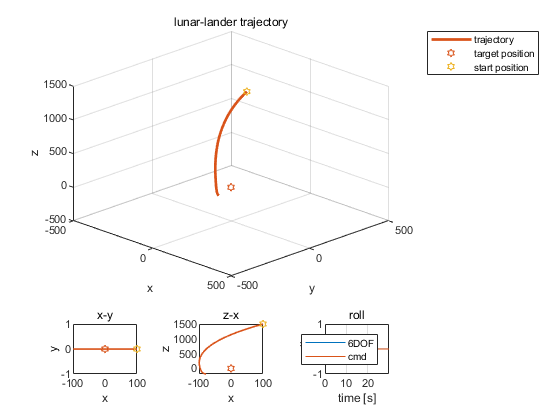

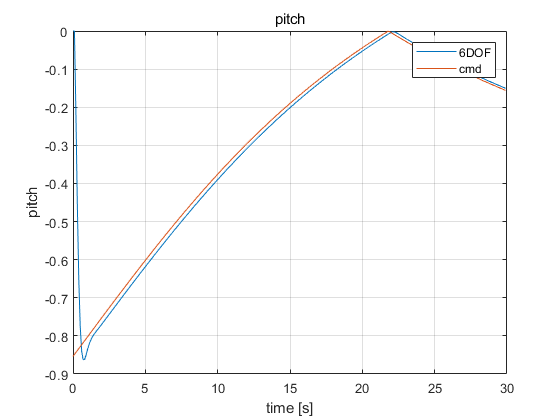

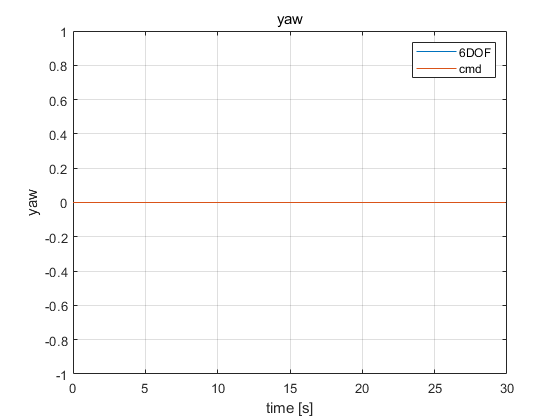

% Trajectory plot
figure('Color','White')
tiledlayout(4,3)
nexttile([3 3])
plot3(save_state(:,1),save_state(:,2),-save_state(:,3),'Color','#D95319','LineWidth',2);
hold on
title('lunar-lander trajectory')
xlabel('x'); ylabel('y'); zlabel('z');
ylim([-500 500]);
xlim([-500 500]);
view(45, 30)
grid on

plot3(state_t(1),state_t(2),-state_t(3),'h');
plot3(initial_state(1),initial_state(2),-initial_state(3),'h');
legend('trajectory','target position','start position')
hold off

nexttile;
plot(save_state(:,1),save_state(:,2),'Color','#D95319','LineWidth',1.2); hold on;
title('x-y')
xlabel('x'); ylabel('y');
plot(state_t(1),state_t(2),'h');
plot(initial_state(1),initial_state(2),'h');
hold off

nexttile;
plot(save_state(:,1),-save_state(:,3),'Color','#D95319','LineWidth',1.2); hold on
title('z-x')
xlabel('x'); ylabel('z');
plot(state_t(1),-state_t(3),'h');
plot(initial_state(1),-initial_state(3),'h');
hold off

nexttile;
plot(save_state(:,2),-save_state(:,3),'Color','#D95319','LineWidth',1.2); hold on
title('z-y')
xlabel('y'); ylabel('z');
plot(state_t(2),-state_t(3),'h');
plot(initial_state(2),-initial_state(3),'h');
hold off
% ts = linspace(0,t_go,50);
% plot(ts, acc_(:,1))

% % Trajectory animation plot
% x_min = min(save_state(:,1));
% x_max = max(save_state(:,1));
% y_min = min(save_state(:,2));
% y_max = max(save_state(:,2));
% z_min = h-min(100 - save_state(:,3));
% z_max = h-max(100 - save_state(:,3));
% figure('Color','White')
% pause(1)
% hold on
% for i = 1 : length(save_state(:,1))
%     ax = gcf;
%     plot3(save_state(i,1),save_state(i,2),h-save_state(i,3),'.b');
%     title('lunar-lander trajectory - Animate')
%     xlabel('x'); ylabel('y'); zlabel('z');
%     grid on
%     pause(0.1)
%     view(45, 30)
%     xlim([x_min x_max])
%     ylim([y_min y_max])
% %     zlim([z_min z_max])
% end
% hold off
% % states
figure('Color','White')
tiledlayout(3,3)
tf = length(save_state(:,1)) * dt;
for i = 7 : 9
    figure(i-6)
    plot(0:dt:tf-dt, save_state(:,i),0:dt:tf-dt, angle_cmd(:,i-6));
%     plot(0:dt:tf-dt, angle_cmd(:,i-6));
    xlabel('time [s]')
    id = state_id(i);
    title(id)
    ylabel(id)
    legend('6DOF','cmd')
    grid on
end

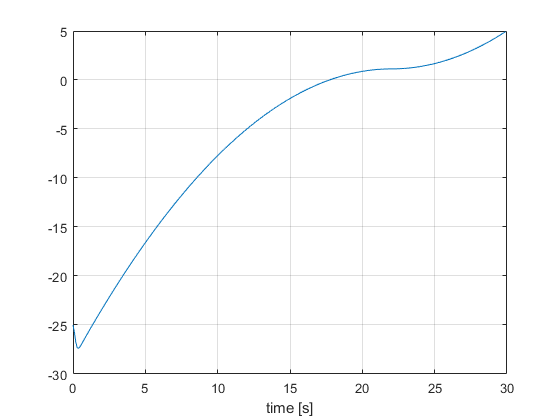

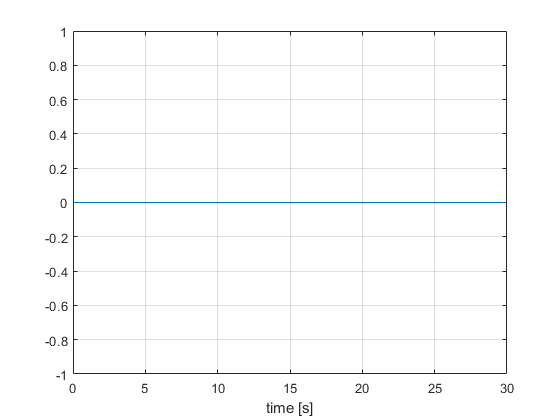

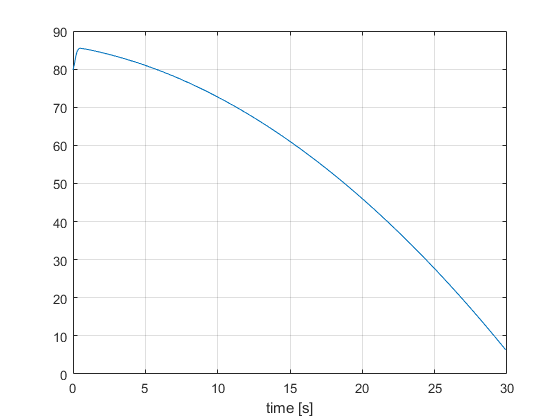


for i = 1 : 3
    figure()
    plot(0:dt:tf-dt, V_ned(:,i));
    xlabel('time [s]')
    grid on
end